clear;

% Load ROS bag
dataPath = "E:\ICRA2\radar_high_res\2020-07-13-14-10-09.bag";
bag = rosbag(dataPath);

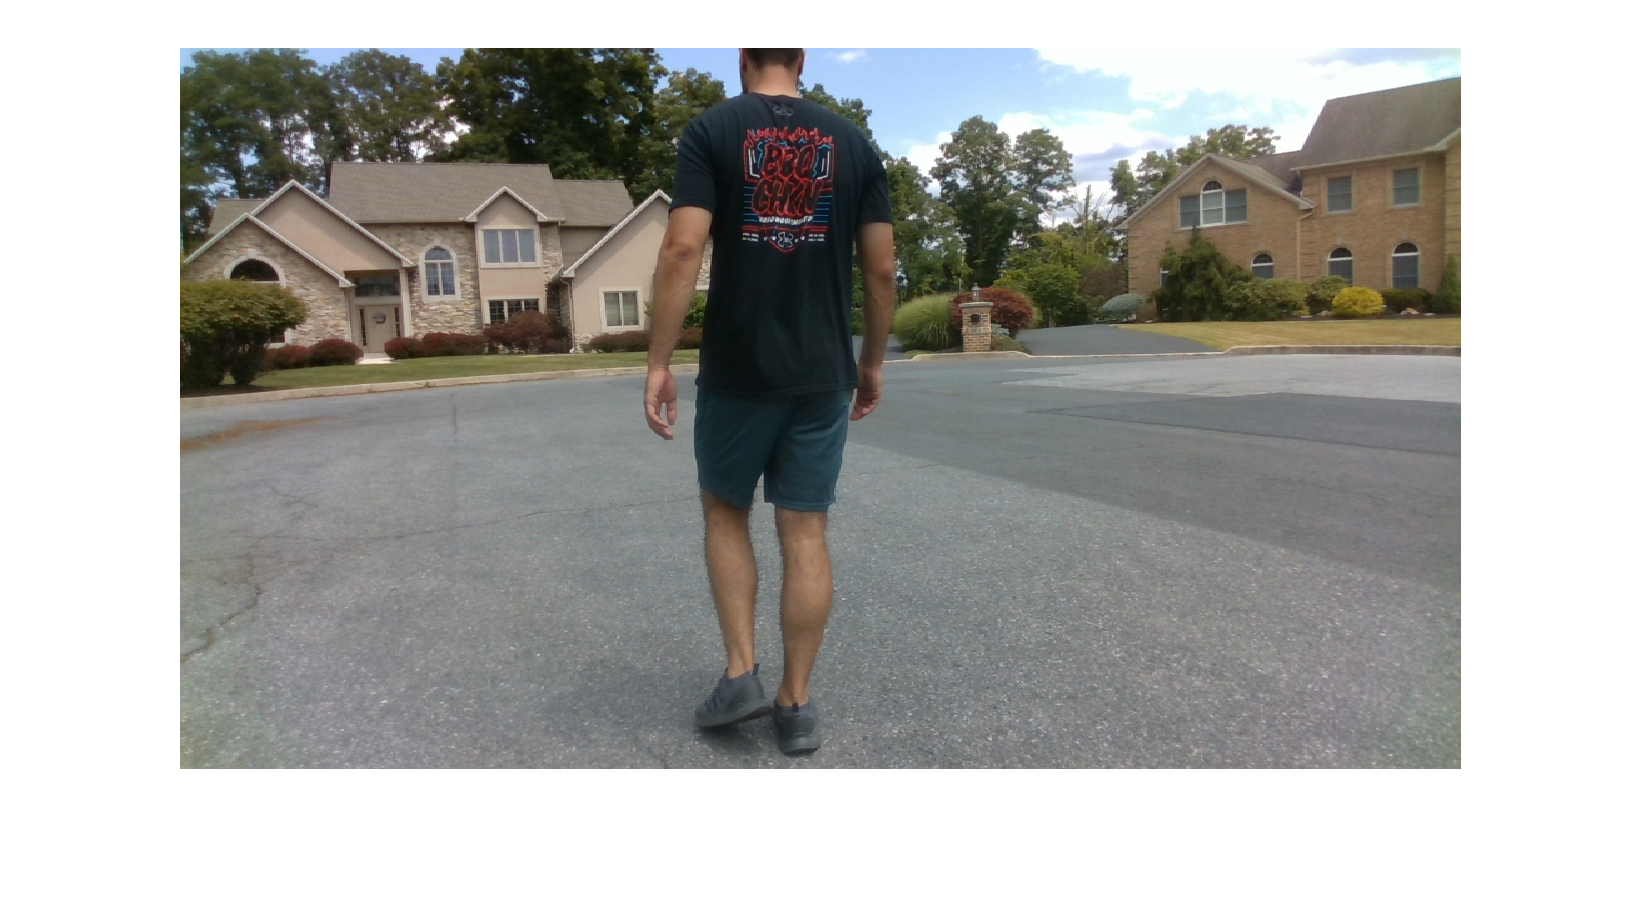

% Extract images and view one 
images = select(bag, "MessageType", "sensor_msgs/Image", "Topic", "/camera/color/image_raw");
image1 = readMessages(images, [1], "DataFormat","struct");
imshow(rosReadImage(image1{1, 1}))

% Extract radar data 
radars = select(bag, "MessageType", "mmWave/data_frame", "Topic", "/radar_data");
radar1 = readMessages(radars, "DataFormat","struct");


dataCube = build_data_cube_4(radar1{1100, 1}.Data, 304, 4, 2, 256, 4); 
disp(size(dataCube));

   304     8   128




nfft_r = 2^nextpow2(size(dataCube, 1));
rangeProc = fft(dataCube(:, :, :), nfft_r, 1);
disp(size(rangeProc));

   512     8   128



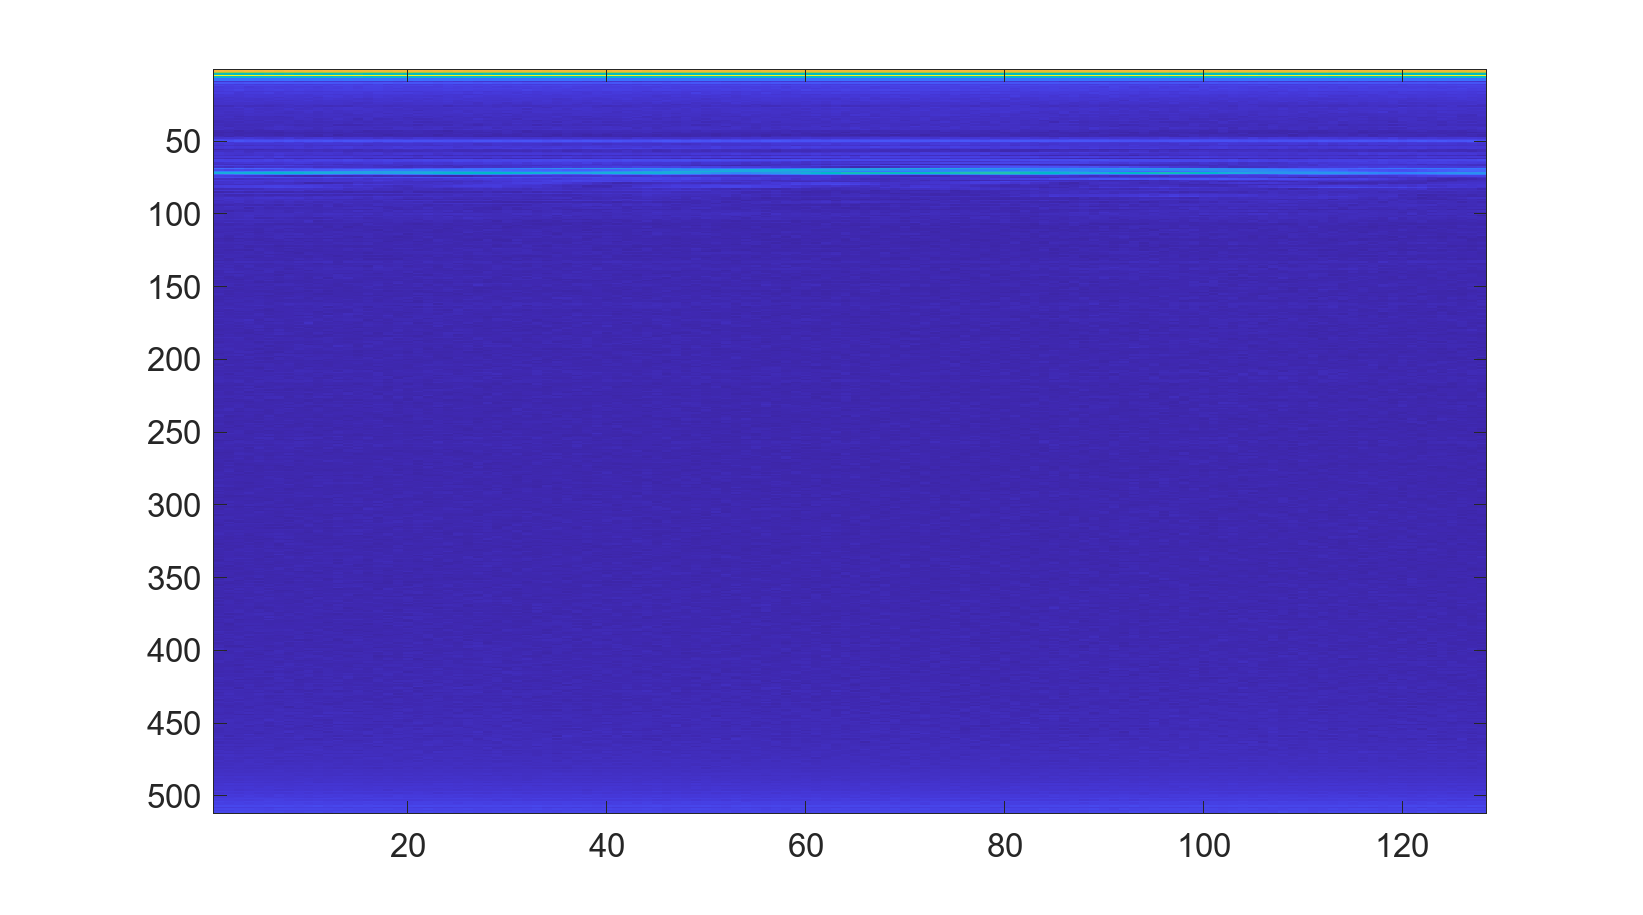

imagesc(abs(squeeze(rangeProc(:, 1, :))));


nfft_d = 2^nextpow2(size(dataCube, 3));
rdProc = fftshift(fft(rangeProc, nfft_d, 3), 3);
disp(size(rdProc));

   512     8   128



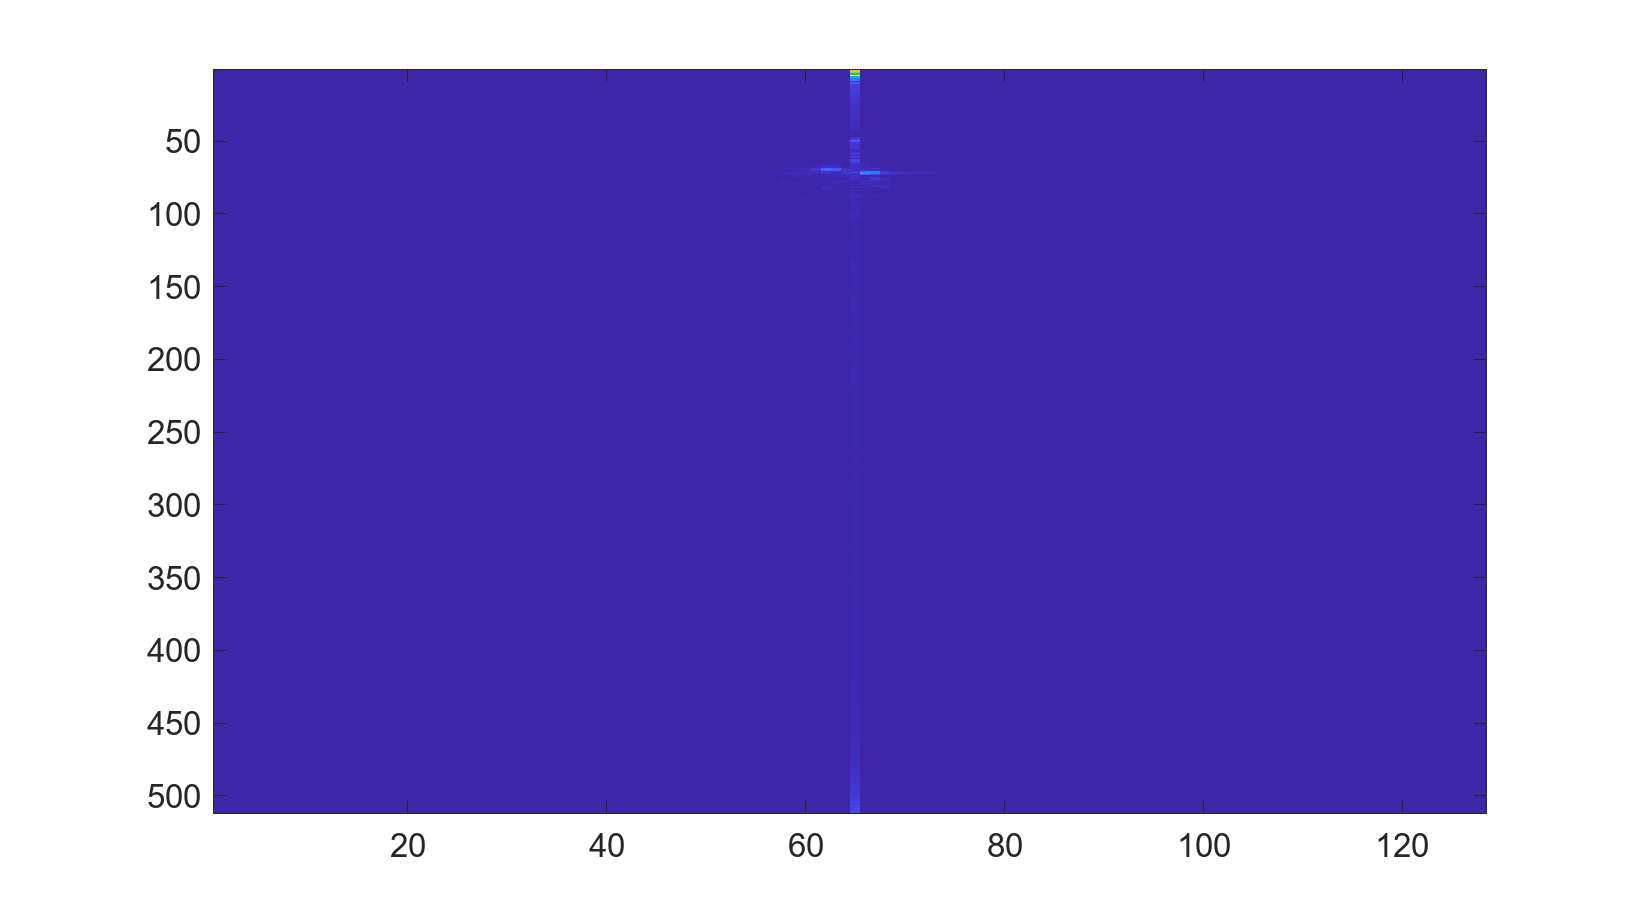

imagesc((abs(squeeze(rdProc(:, 1, :)))));


nfft_a = 2^nextpow2(size(dataCube, 2));
raProc = fftshift(fft(rdProc(:, 1:8, :), 64, 2), 2);
disp(size(raProc));

   512    64   128



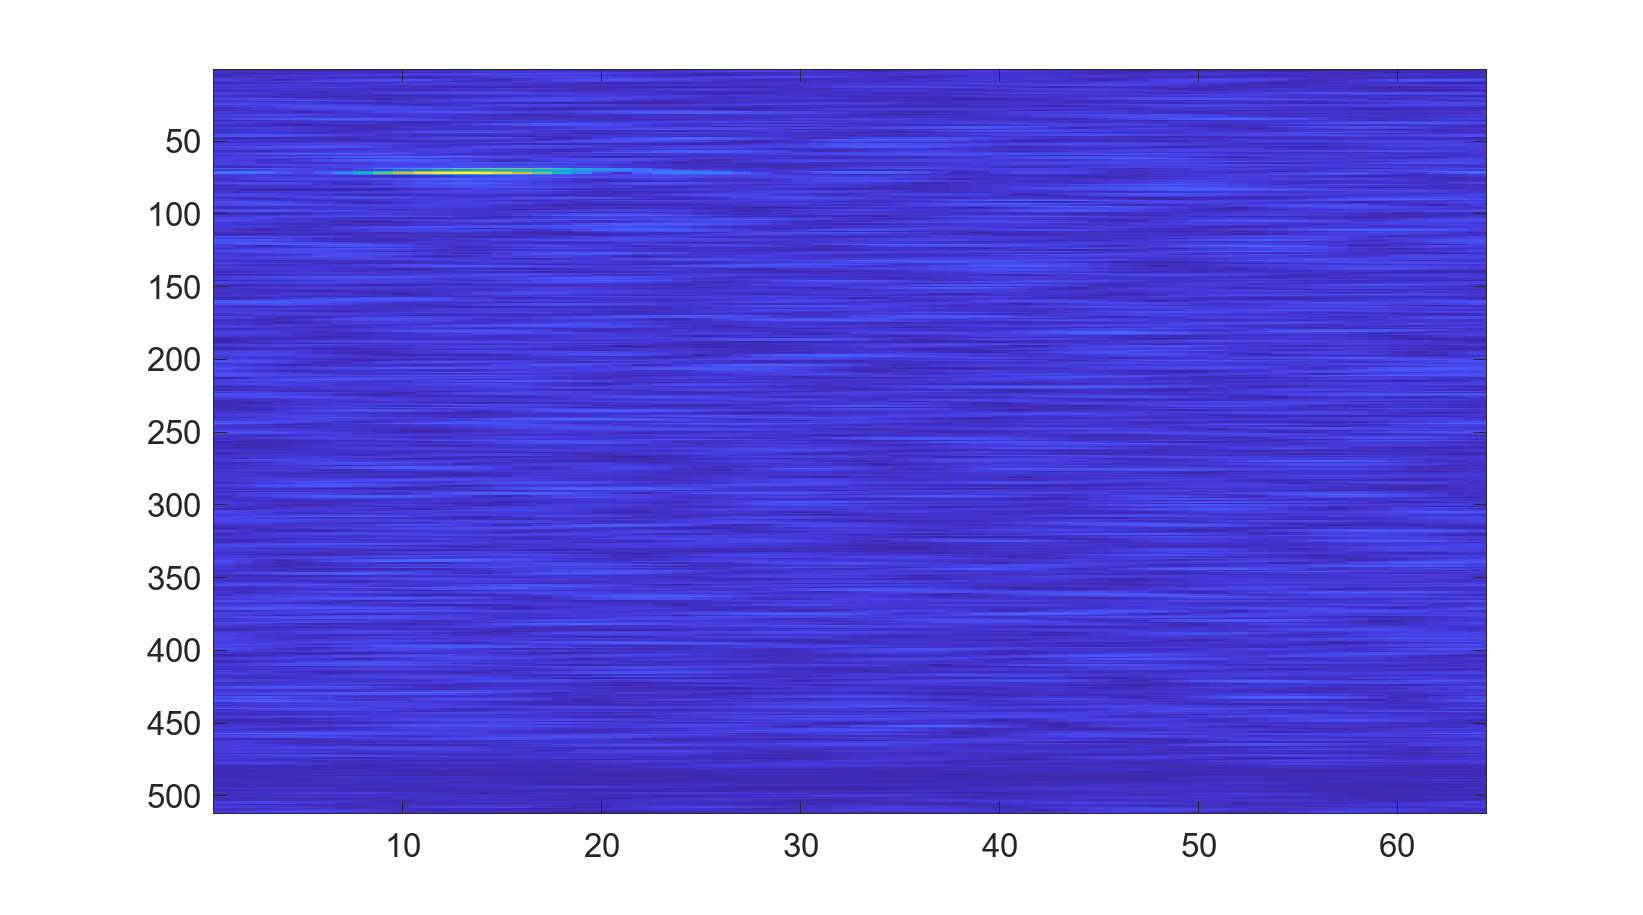

imagesc((abs(squeeze(raProc(:, :, 1)))));


% Range processing 
nfft_r = 2^nextpow2(size(dataCube, 1));
c = physconst('LightSpeed');
fs = 9499000.0;
fc = 77e9;
ramp_end_time = 3.668e-05;
idle_time = 0.000135;
tm = ramp_end_time + idle_time;
PRF = 1 / tm;
sweepSlope = 100000000000000.0;
nfft_d = 2^nextpow2(size(dataCube, 3));

rngdop = phased.RangeDopplerResponse('PropagationSpeed',c,...
    'DopplerOutput','Speed','OperatingFrequency',fc,'SampleRate',fs,...
    'RangeMethod','FFT','PRFSource','Property',...
    'RangeWindow','Hann','PRF',PRF,...
    'SweepSlope',sweepSlope,...
    'RangeFFTLengthSource','Property','RangeFFTLength',nfft_r,...
    'DopplerFFTLengthSource','Property','DopplerFFTLength',nfft_d,...
    'DopplerWindow','Hann', ReferenceRangeCentered=1);

plotResponse(rngdop, squeeze(dataCube(:, 1, :)));

[resp, r, sp] = rngdop(dataCube);

% imagesc(abs(squeeze(resp(:, 1, :))))

ra = fft(resp, 64, 2);

imagesc(abs(squeeze(ra(:, :, 1))));


range_doppler = VideoWriter('radar_rd_5.mp4', 'MPEG-4');
range_angle = VideoWriter('radar_ra_5.mp4', 'MPEG-4');
range_doppler.FrameRate = 30;  % Adjust frame rate as needed
range_doppler.Quality = 90;    % Adjust quality as needed
range_angle.FrameRate = 30;  % Adjust frame rate as needed
range_angle.Quality = 90;    % Adjust quality as needed
open(range_doppler);
open(range_angle);


for i = 1:numel(radar1)
    currentCell = radar1{i, 1};
    % Process radar data 
    disp(i)
    dataCube = build_data_cube_4(currentCell.Data, 304, 4, 2, 256, 4); 
    nfft_r = 2^nextpow2(size(dataCube, 1));
    rangeProc = (fft(dataCube(:, :, :), nfft_r, 1));
    
    nfft_d = 2^nextpow2(size(dataCube, 3));
    rdProc = fftshift(fft(rangeProc, nfft_d, 3), 3);

    % nfft_a = 2^nextpow2(size(dataCube, 2));
    raProc = fftshift(fft(rangeProc, 512, 2), 2);

    

    writeVideo(range_doppler, (uint8(log(abs(squeeze(rdProc(:, 1, :)))))));
    writeVideo(range_angle, (uint8(log(abs(squeeze(raProc(:, :, 1)))))));
end 

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101

   102

   103

   104

   105

   106

   107

   108

   109

   110

   111

   112

   113

   114

   115

   116

   117

   118

   119

   120

   121

   122

   123

   124

   125



close(range_doppler);
close(range_angle);